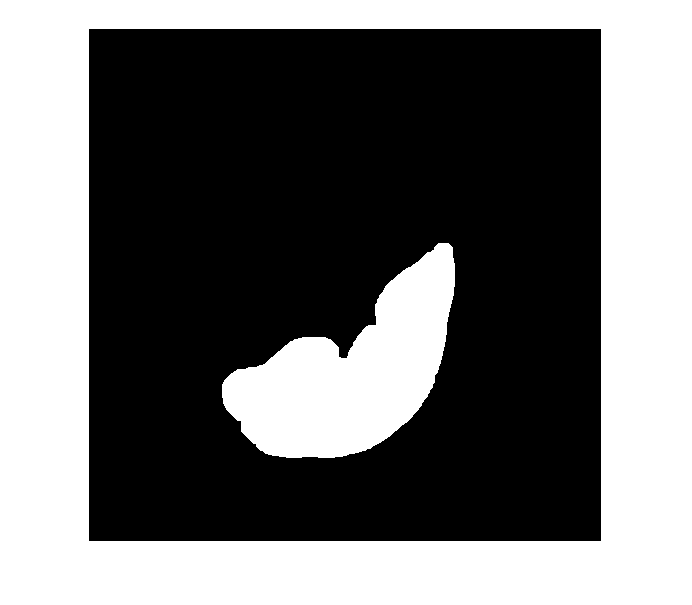

file_read = ('volume-125.nii');
nii=load_nii(file_read);
img=nii.img;
[n1,n2,n3]=size(img);
img=mat2gray(img);
z=205;%选择需要分割的图层
I=img(:,:,z);

%分割肝脏
J1=Get_liver(I,355,277,0.005);%手动选择种子点

%分割肿瘤
    if(z>=215&&z<=222)%所选数据集中肿瘤对应像素点很少，仅在较少图层中
            J2=Get_tumour(I,315,188,0.007,n1,n2);%手动选择种子点
    else
            J2=zeros(n1,n2);
    end
J3=J1+J2;%将分割出的肝脏与肿瘤合并
J3=make_nii(J3);
file_write = ('result\205.nii');
save_nii(J3,file_write);%保存成nii格式




%评估部分
clear()
clc;

file_read =("result\205.nii");
nii=load_nii(file_read{1});
image=nii.img;
s3=("segmentation-125.nii");
sd3=load_nii(s3{1});
standard=sd3.img;
[m1,m2,m3]=size(standard);
  TP=0;%真正例
  FP=0;%假正例
  TN=0;%真反例
  FN=0;%假反例
  k=205; %z轴
  for i=1:m1
      for j=1:m2
              if image(i,j)>=1&&standard(i,j,k)>=1
                  TP=TP+1;
              end
              if image(i,j)>=1&&standard(i,j,k)==0
                   FP=FP+1;
              end
              if image(i,j)==0&&standard(i,j,k)==0
                  TN=TN+1;
              end
               if image(i,j)==0&&standard(i,j,k)>=1
                   FN=FN+1;
             
          end
      end
  end
  IOU=roundn(TP/(TP+FN+FP),-5);%分割结果与标签的交并比
  Dice_score=roundn(2*TP/(2*TP+FP+FN),-5);%骰子系数，两个相似度
  Sensitivity=roundn(TP/(TP+FN),-5);%灵敏度，将的确是病灶的区域正确地判断为病灶
  Specificity=roundn(TN/(TN+FP),-5);%特异度，将不是病灶的区域正确地判断为非病灶
  Precision=roundn(TP/(TP+FP),-5);%预测准确度，预测为病灶的地方的确为病灶
  MPA=roundn(((TP+TN)/(FN+TP+FP+TN)),-5);%计算正确预测的像素与所有像素数量的比值
  all=[IOU,Dice_score,Sensitivity,Specificity,Precision,MPA];